
% Defining the variables: Angle q, length l_0, length l_1, length l_2
syms q l_0 l_1 l_2 l_ee
q = 0;
l_0 = 0.2;
l_1 = 2;
l_2 = 1.9;
l_ee = 1;
% From frame 0 to frame 1
T0_1 = [cos(q) -sin(q) 0 0; sin(q) cos(q) 0 0; 0 0 1 l_0; 0 0 0 1]

T0_1 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.2000
         0         0         0    1.0000



% From frame 1 to frame 2
T1_2 = [1 0 0 0; 0 0 1 0; 0 -1 0 l_1; 0 0 0 1]

T1_2 =      1     0     0     0
     0     0     1     0
     0    -1     0     2
     0     0     0     1



% From frame 2 to frame 3
T2_3 = [1 0 0 0; 0 0 1 0; 0 -1 0 l_2; 0 0 0 1]

T2_3 =     1.0000         0         0         0
         0         0    1.0000         0
         0   -1.0000         0    1.9000
         0         0         0    1.0000



% From frame 3 to end effector frame
T3_4 = [1 0 0 0; 0 1 0 0; 0 0 1 l_ee; 0 0 0 1]

T3_4 =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1



% End effector pose
TEE = T0_1 * T1_2 * T2_3 * T3_4;


% Display TEE with 3 decimal places
TEE_vpa = vpa(TEE, 3);
disp('TEE matrix with 5 decimal places:');

TEE matrix with 5 decimal places:


disp(TEE_vpa);

$$\left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & -1.0 & 0 & 1.9\\ 0 & 0 & -1.0 & 1.2\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$


%final pose
position = TEE(1:3, 4);
position_vpa = vpa(position, 3)

$$position\_vpa = \left(\begin{array}{c} 0\\ 1.9\\ 1.2 \end{array}\right)$$

orientation = TEE(1:3, 1:3);
orientation_vpa = vpa(orientation, 3)% Extract the 3x3 rotation matrix

$$orientation\_vpa = \left(\begin{array}{ccc} 1.0 & 0 & 0\\ 0 & -1.0 & 0\\ 0 & 0 & -1.0 \end{array}\right)$$

%Inverse Kinematics
%Desired end effector pose

% Define symbolic variables
syms e_1 e_2 e_ee

% Constants
x = 2;
y = 2; 
z = 3;
l0 = 1;
angle = atan(x / y)*180/pi % Compute q numerically

angle = 45


% Define equations
l2 = y/cos(angle)

l2 = 3.8072

dif_l1lee = z-l0

dif_l1lee = 2

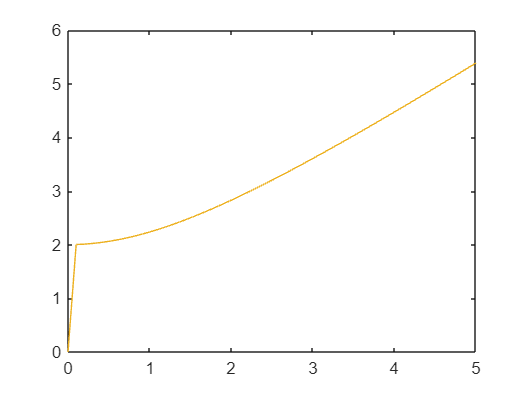

X = 2;
Y = 0:0.1:5;
Z = 0:0.1:5;
L2 = Y./(cos(atan(X./Y)));
plot(Y,L2)
hold on
X = 3;
plot(Y,L2)
X = 4;
plot(Y,L2)
hold off

% Define symbolic variables for joint parameters
syms q l_0 l_1 l_2 l_ee real % Joint variables and link lengths

% Transformation matrices (same as given)
T0_1 = [cos(q), -sin(q), 0, 0; 
        sin(q),  cos(q), 0, 0; 
         0,      0,      1, l_0; 
         0,      0,      0, 1];

T1_2 = [1, 0, 0, 0; 
        0, 0, 1, 0; 
        0, -1, 0, l_1; 
        0, 0, 0, 1];

T2_3 = [1, 0, 0, 0; 
        0, 0, 1, 0; 
        0, -1, 0, l_2; 
        0, 0, 0, 1];

T3_4 = [1, 0, 0, 0; 
        0, 1, 0, 0; 
        0, 0, 1, l_ee; 
        0, 0, 0, 1];

% Compute full transformation matrix
TEE = T0_1 * T1_2 * T2_3 * T3_4;

% Extract end-effector position
position = TEE(1:3, 4);

% Initialize Jacobian matrices
Jv = sym(zeros(3, 4)); % Linear velocity Jacobian (only 1 joint for now)
Jw = sym(zeros(3, 4)); % Angular velocity Jacobian

% Define joint axis and origins for each transformation
z0 = [0; 0; 1]; % z-axis of frame 0
o0 = [0; 0; 0]; % Origin of frame 0

% Compute linear velocity Jacobian for revolute joint
Jv(:, 1) = cross(z0, (position - o0)); % Linear velocity due to revolute joint
Jw(:, 1) = z0; % Angular velocity due to revolute joint

% Display results
disp('Linear Velocity Jacobian (Jv):');

Linear Velocity Jacobian (Jv):


disp(simplify(Jv));

$$\left(\begin{array}{cccc} -l_{2}\,\cos\left(q\right) & 0 & 0 & 0\\ -l_{2}\,\sin\left(q\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


disp('Angular Velocity Jacobian (Jw):');

Angular Velocity Jacobian (Jw):


disp(simplify(Jw));

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 \end{array}\right)$$


% Combine Jacobian
Jacobian = [Jv; Jw]; % Full Jacobian (6x1 for 1 DOF initially)
disp('Full Jacobian Matrix:');

Full Jacobian Matrix:


disp(simplify(Jacobian));

$$\left(\begin{array}{cccc} -l_{2}\,\cos\left(q\right) & 0 & 0 & 0\\ -l_{2}\,\sin\left(q\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 \end{array}\right)$$


% Desired end-effector velocity (linear velocity only for simplicity)
v_EE = [0.5; 0; 0]; % In meters per second

% Full Jacobian (linear + angular velocities)
Jacobian = [Jv; Jw]; % Use the Jacobian from earlier

% Compute joint velocities using the pseudo-inverse of the Jacobian
joint_velocities = pinv(Jacobian) * [v_EE; zeros(3, 1)]; % Assume no angular velocity for simplicity

disp('Joint velocities required for desired end-effector velocity:');

Joint velocities required for desired end-effector velocity:


disp(vpa(joint_velocities, 3));

$$\left(\begin{array}{c} -\frac{0.5\,l_{2}\,\cos\left(q\right)}{{l_{2}}^{2}\,{\cos\left(q\right)}^{2}+{l_{2}}^{2}\,{\sin\left(q\right)}^{2}+1.0}\\ 0\\ 0\\ 0 \end{array}\right)$$